
T_oe=244800;
%a_s=;%卫星星历
sqrta_s=5153.65531;
e_s=0.0059120386265;
i_0=0.9848407943;
Omega_0=1.0380625244;
omega=-1.717457876;%卫星星历
M_0=-1.064739758;%卫星星历
delta_n=4.249105564*10^(-9);
dot_i=7.422851197*10^(-51);
dot_Omega=-8.151768125*10^(-9);
C_uc=3.054738045*10^(-7);
C_us=2.237036824*10^(-6);
C_rc=350.53125;
C_rs=2.53125;
C_ic=-8.381903172*10^(-8);
C_is=8.940696716*10^(-8);
mu=3.986005*10^(14);
pi=3.1415926535898;
dot_Omega_e=7.2921151467*10^(-5);

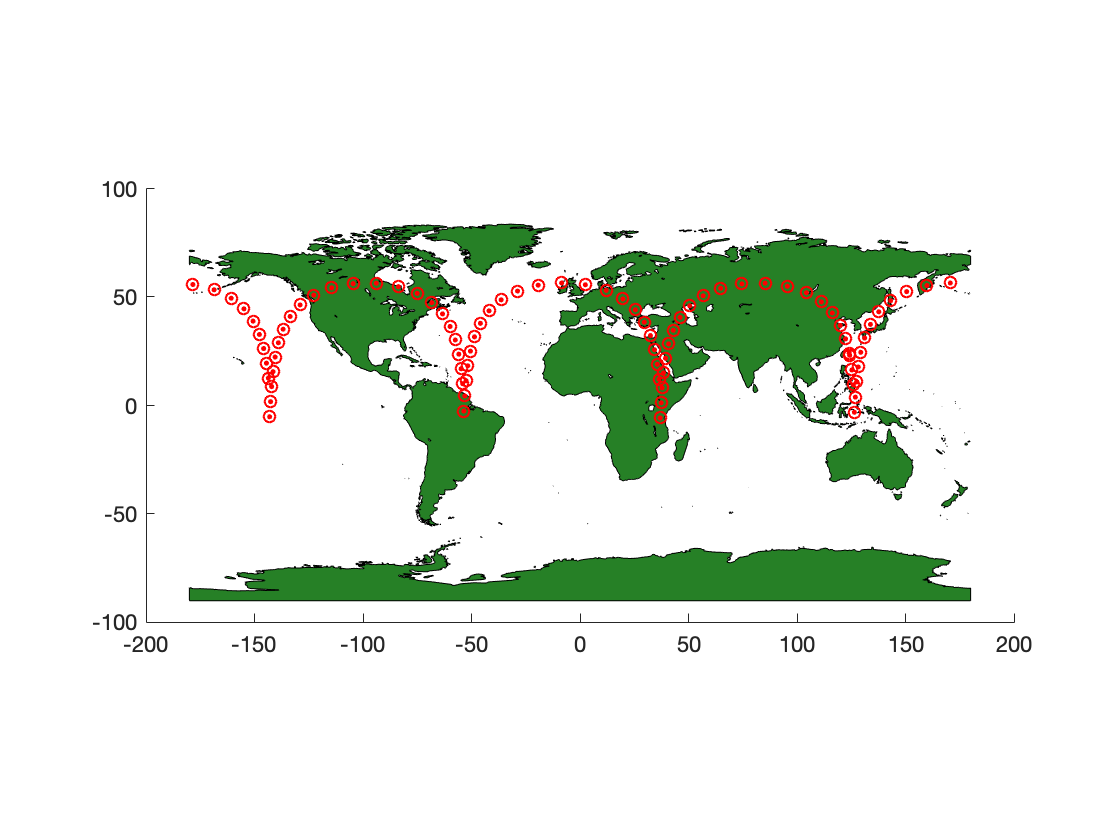

for t=239050.7223:1000:325450.7223;
    n_m=1+round((t-239050.7223)/1000);
    n_0=sqrt(mu/(sqrta_s^6));
    
    T_k=t-T_oe;
    n=n_0-delta_n;
    M_k=(M_0+n*T_k);
    E(1)=M_k;
    for i=2:1:3
        E(i)=M_k+2*pi+e_s*sin(E(i-1));
    end
    E_k=E(i);
    cosv=(cos(E_k)-e_s)/(1-e_s*cos(E_k));
    sinv=(sqrt(1-e_s^2)*sin(E_k))/(1-e_s*cos(E_k));
    v_k=atan(sinv/cosv)-pi;
    Phi_k=v_k+omega;
    deltau_k=C_us*sin(2*Phi_k)+C_us*cos(2*Phi_k);
    deltar_k=C_rs*sin(2*Phi_k)+C_rs*cos(2*Phi_k);
    deltai_k=C_is*sin(2*Phi_k)+C_is*cos(2*Phi_k);
    u_k=Phi_k+deltau_k;
    r_k=(sqrta_s^2)*(1-e_s*cos(E_k))+deltar_k;
    i_k=i_0+dot_i*T_k+deltai_k;
    x1_k=r_k*cos(u_k);
    y1_k=r_k*sin(u_k);
    Omega_k=Omega_0+(dot_Omega-dot_Omega_e)*T_k-dot_Omega_e*T_oe;
    x_k(n_m)=x1_k*cos(Omega_k)-y1_k*cos(i_k)*sin(Omega_k);
    y_k(n_m)=x1_k*sin(Omega_k)+y1_k*cos(i_k)*cos(Omega_k);
    z_k(n_m)=y1_k*sin(i_k);

    
    
    a = 6378137;
    f = 1/298.257223563;
    e2 = 2 * f - f^2;
    %算大地经度，反正切修正
    L(n_m) = atan(y_k(n_m)/x_k(n_m));
    if x_k(n_m) < 0
        L(n_m) = L(n_m) + pi;
    elseif y_k(n_m) < 0 && x_k(n_m) > 0
        L(n_m) = L(n_m) + 2*pi;
    end
    L(n_m)= L(n_m) * 180 / pi - 180;
    %大地纬度，设初值，迭代
    B(n_m) = atan(z_k(n_m) / sqrt(x_k(n_m)^2 + y_k(n_m)^2));
    Btemp = 20;
    while abs(B(n_m) - Btemp) > 1e-11
        N = a / sqrt(1 - e2 * (sin(B(n_m)))^2);
        H(n_m) = sqrt(x_k(n_m)^2 + y_k(n_m)^2) / cos(B(n_m)) - N;
        Btemp = B(n_m);
        B(n_m) = atan(z_k(n_m)/ sqrt(x_k(n_m)^2 + y_k(n_m)^2) / (1 - e2 * N / (N + H(n_m))));
    end
    H(n_m) = z_k(n_m)/ sin(B(n_m)) - N * (1 - e2);
    B(n_m) = B(n_m) * 180 / pi;
   
   

end
geoshow('landareas.shp','FaceColor', [0.15 0.5 0.15]),hold on % 绘制底图地球
for j=1:1:n_m
plot(L(j),B(j),'ro'); % 绘制坐标
pause(0.1);
end